auxiliary plot functions

aboxplot

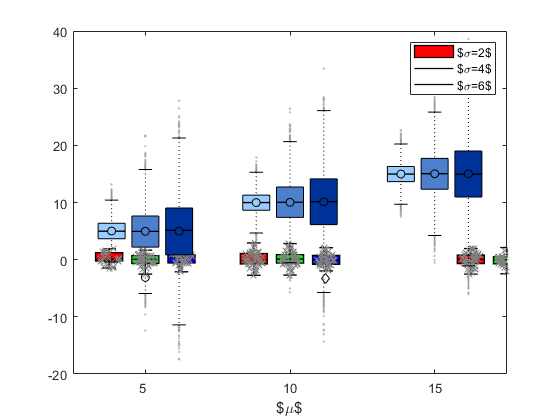

% First group of 3 data set with standard deviation 2
x1 = normrnd(5,2,10000,1);
x2 = normrnd(10,2,10000,1);
x3 = normrnd(15,2,10000,1);
% Second group of 3 data set with standard deviation 4
y1 = normrnd(5,4,10000,1);
y2 = normrnd(10,4,10000,1);
y3 = normrnd(15,4,10000,1);
% Third group of 3 data set with standard deviation 6
z1 = normrnd(5,6,10000,1);
z2 = normrnd(10,6,10000,1);
z3 = normrnd(15,6,10000,1);

% Concatenate the data sets from each group in a 10000 x 3 matrix
x = cat(2,x1,x2,x3); 
y = cat(2,y1,y2,y3);
z = cat(2,z1,z2,z3);

h = {x;y;z}; % Create a cell array with the data for each group

aboxplot(h,'labels',[5,10,15]); % Advanced box plot

xlabel('$\mu$'); % Set the X-axis label

legend('$\sigma=2$','$\sigma=4$','$\sigma=6$'); % Add a legend

boxplot2

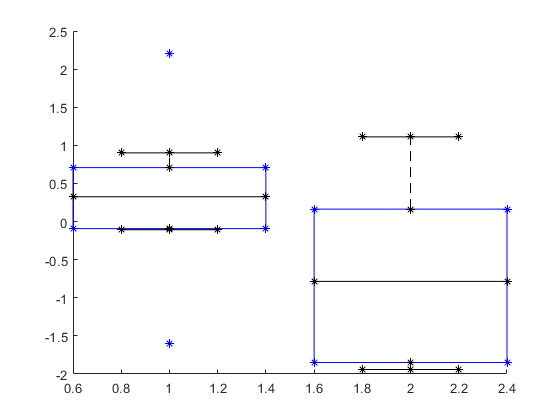

figure,
h = boxplot2(randn(10,2));
set(h.med,'color','k');
structfun(@(x) set(x,'marker','*'),h);

iosr

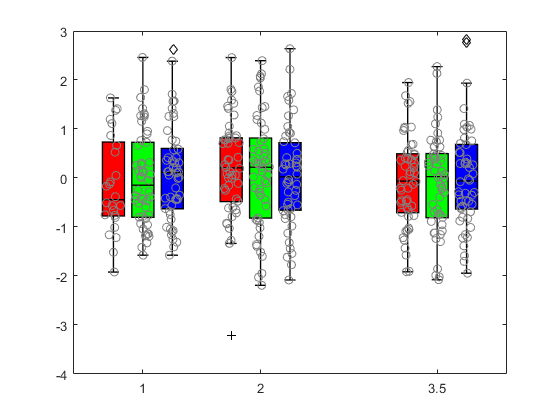

y = randn(50,3,3);
x = [1 2 3.5];
y(1:25) = NaN;

figure;
h = iosr.statistics.boxPlot(x,y,...
    'symbolColor','k',...
    'medianColor','k',...
    'symbolMarker',{'+','o','d'},...
    'boxcolor',{[1 0 0]; [0 1 0]; [0 0 1]},...
    'groupLabels',{'y1','y2','y3'},...
    'showScatter',true, ...
    'scatterMarker','o');
box on